# Instruction of AI Drivers

## 1. Overview

This file is to introduce the MAT-files and models of AI drivers, as well as how to apply these models as the longitudinal driving controller in MOBATSim.

## 2. File introduction

- Folder "BC_Feature": This folder contains two files, the m-file "[BC_feature.m](matlab:open('./BC_Feature\BC_feature.m'))" is to load the trained behavioral cloning feature network "[BC_feature.mat](matlab:open('./BC_Feature\BC_feature.mat'))" in this folder into a Simulink block "*Matlab System*", where it is located at "*AI_Drivers/Longitudinal Speed Control BC_feature/Matlab System*" in the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))".

- Folder "BC_LSTM": This folder contains three files, the trained behavioral cloning Long Short Time Memory (LSTM) network "[BiLSTMnet.mat](matlab:open('./BC_LSTM\BiLSTMnet.mat'))" is loaded in the Simulink block "*predict*", where it is located at "*AI_Drivers/Longitudinal Speed Control BC_LSTM/LSTM_prediction/Predictor*" in the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))". As for "[LSTM_mu.mat](matlab:open('./BC_LSTM\LSTM_mu.mat'))" and "[LSTM_sig.mat](matlab:open('./BC_LSTM\LSTM_sig.mat'))", they are used to norminlize the training data in real time and they are loaded into the Simulink block "*From file*", where they are located at "*AI_Drivers/Longitudinal Speed Control BC_LSTM/LSTM_prediction/Mu File*" and "*AI_Drivers/Longitudinal Speed Control BC_LSTM/LSTM_prediction/Sig File*" in the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))".

- Folder "DDPG": This folder contains three files, the m-file "[DDPG.m](matlab:open('./DDPG\DDPG.m'))" is to load the trained reinforcement learning DDPG Actor network "[DDPGVehicleFollow.mat](matlab:open('./DDPG\DDPGVehicleFollow.mat'))" in this folder into a Simulink block "*Matlab System*", where it is located at "*AI_Drivers/Longitudinal Speed Control DDPG/Matlab System*" in the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))". Note that there is another trained DDPG network "[AgentDDPG.mat](matlab:open('./DDPG\AgentDDPG.mat'))", which could be loaded into the Simulink Block "RL agent". Different from the Actor network "[DDPGVehicleFollow.mat](matlab:open('./DDPG\DDPGVehicleFollow.mat'))" only includes the actor network, the general network "[AgentDDPG.mat](matlab:open('./DDPG\AgentDDPG.mat'))" includes the actor network and critic network, i.e. the Actor network "[DDPGVehicleFollow.mat](matlab:open('./DDPG\DDPGVehicleFollow.mat'))" could be derivated from the general network "[AgentDDPG.mat](matlab:open('./DDPG\AgentDDPG.mat'))" in the following way:

% First get into the DDPG folder
load('AgentDDPG.mat','saved_agent');
agent = saved_agent;
VehicleFollow=getModel(getActor(agent));
save("DDPGVehicleFollow.mat","VehicleFollow")

- Folder "DQN": This folder contains four files, the m-file "[DQN.m](matlab:open('./DQN\DQN.m'))" is to load the trained reinforcement learning DQN Critic network "[DQNVehicleFollow.mat](matlab:open('./DQN\DQNVehicleFollow.mat'))" in this folder into a Simulink block "*Matlab System*", where it is located at "*AI_Drivers/Longitudinal Speed Control DQN/Matlab System*" in the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))". Simliar to the DDPG, the general network "[AgentDQN.mat](matlab:open('./DQN\AgentDQN.mat'))" could be loaded into the Simulink Block "RL agent". Since there is only one critic network in the general DQN network, the Critic network "[DQNVehicleFollow.mat](matlab:open('./DQN\DQNVehicleFollow.mat'))" could be derivated from the general network "[AgentDQN.mat](matlab:open('./DQN\AgentDQN.mat'))" in the following way:

% First get into the DQN folder
load('AgentDQN.mat','saved_agent');
agent = saved_agent;
VehicleFollow=getModel(getCritic(agent));
save("DQNVehicleFollow.mat","VehicleFollow")

There is a txt file called "[Known Issues.txt](matlab:open('./DQN\Known Issues.txt'))", which records the possible error message and provides possible solutions.

- Folder "TD3": This folder contains three files, the m-file "[TD3.m](matlab:open('./TD3\TD3.m'))" is to load the trained reinforcement learning TD3 Actor network "[TD3VehicleFollow.mat](matlab:open('./TD3\TD3VehicleFollow.mat'))" in this folder into a Simulink block "*Matlab System*", where it is located at "*AI_Drivers/Longitudinal Speed Control TD3/Matlab System*" in the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))". Similar to before, the general network "[AgentTD3.mat](matlab:open('./TD3\AgentTD3.mat'))" could be loaded into the Simulink Block "RL agent". The Critic network "[TD3VehicleFollow.mat](matlab:open('./TD3\TD3VehicleFollow.mat'))" could be derivated from the general network "[AgentTD3.mat](matlab:open('./TD3\AgentTD3.mat'))" in the following way:

% First get into the TD3 folder
load('AgentTD3.mat','saved_agent');
agent = saved_agent;
VehicleFollow=getModel(getActor(agent));
save("TD3VehicleFollow.mat","VehicleFollow")

- Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))": This model includes standardized subsystemes of AI drivers agent worked as the longitudinal driving controller.

## 3. How to apply the AI drivers into MOBATSim

When we open "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))", we can find there are three areas:

- Reinforcement learning using the MATLAB System;  

- Reinforcement learning using the "RL" agent;

- Behavioral learning using the MATLAB System.

For the AI drivers in the first and third areas, the usage could be completed in following steps:

(1) Open the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))";

(2) Choose the AI_Driver you want to implement in MOBATSim, only copy the subsystem system block, leave the scopes and inputs;

(3) Insert it instead of the Platoon controller in MOBATSim.

(4) Make sure you browse the relevant .m file or .mat file from the folder and connect these inputs/outputs.

For the AI drivers in the second area, they have two usages, one usage is to be the AI controller as same as the controller in the first area, but follows different steps.

(1) Open the Simulink model "[AI_Drivers.slx](matlab:open('./AI_Drivers.slx'))";

(2) Choose the AI_Driver you want to implement in MOBATSim, only copy the subsystem system block, leave the scopes and inputs;

(3) Insert it instead of the Platoon controller in MOBATSim.

(4) Load the trained general network into workspace. For example, if the DQN agent is loaded, input following code in the command Window:

% Get into corresponding folder, here DQN
load('.\DQN\AgentDQN.mat','saved_agent');
agent = saved_agent;

This variable "agent" is loaded into the Block "RL agent", as the following Figure shows.

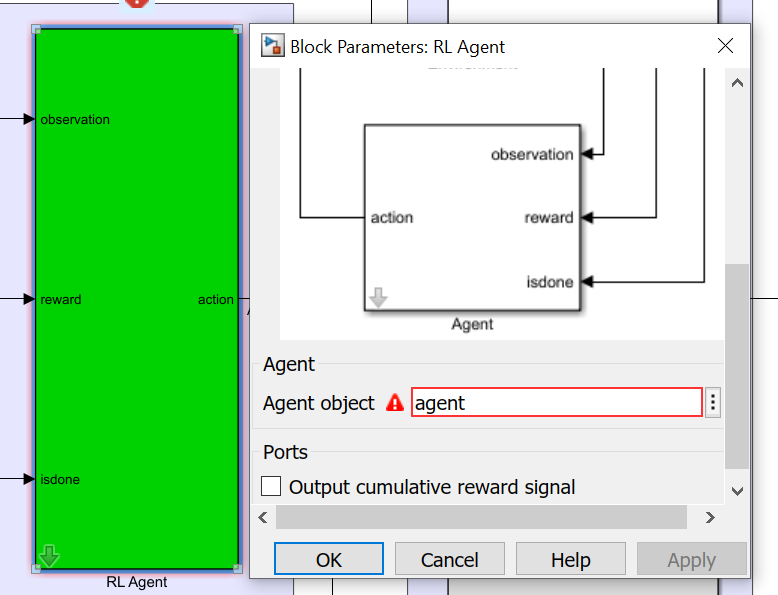

Another usage is to show the reward function and the staus, based on which the corresponding model is trained. For example, let's take a look at the "RL Longitudinal Speed Control Type2".

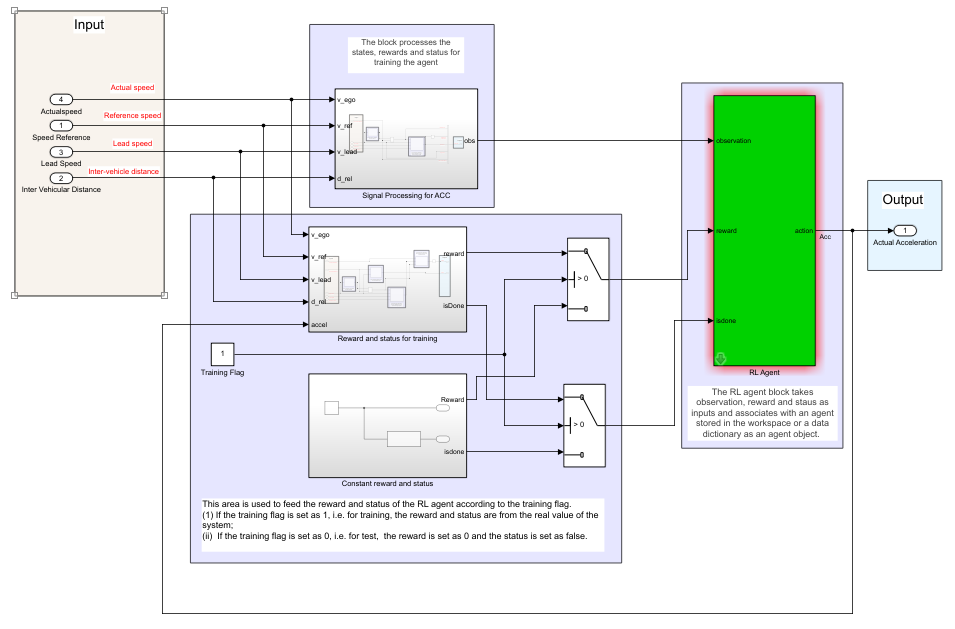

As you can see, there is a constant Block "Training Flag", once it is set as nonzero, which means training mode, i.e. this block can be used to train the correpsonding models; and once it is set as zero, then it is only used to test the loaded trained model.